load gPrices.mat



% ctry = inputdlg('Please enter a country: ')
% 
% idx = strcmpi(ctry,country)

% if any(idx)
%     disp(country(idx))
% else
%     error('no country by that name in data')    
% end

badname = true;

cond = true

while badname && cond
    ctry = inputdlg('Please enter a country: ')

    idx = strcmpi(ctry,country)
    
    badname = ~any(idx);
    
    if badname
        waitfor(errordlg(['no country ', ctry{1},  ' in data']))
    end %if

end %while

ctry =     'Narnia'

idx =    0   0   0   0   0   0   0   0   0   0

ctry =     'France'

idx =    0   0   1   0   0   0   0   0   0   0


ctryPrice = Prices(:,idx);
othersPrice = Prices(:,~idx);
othersName = country(~idx)

othersName =     'Australia'    'Canada'    'Germany'    'Italy'    'Japan'    'Mexico'    'South Korea'    'UK'    'USA'


Slope = zeros(size(othersName)) % preallocate memory

Slope =      0     0     0     0     0     0     0     0     0


for ii = 1:length(othersName)
    % ii
    % othersName(ii)
    c = polyfit(ctryPrice,othersPrice(:,ii),1);
    Slope(ii) = c(1);
    legabv{ii} = [ctry{1}, ' vs ', othersName{ii}]
    fits(:,ii) = c(2) + c(1)*ctryPrice;
    
end

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'

legabv =     'France vs Australia'    'France vs Canada'    'France vs Germany'    'France vs Italy'    'France vs Japan'    'France vs Mexico'    'France vs South Korea'    'France vs UK'    'France vs USA'


Slope

Slope =     0.6935    0.6373    1.1991    0.9344    0.4621    0.2476    0.9137    1.1382    0.5443

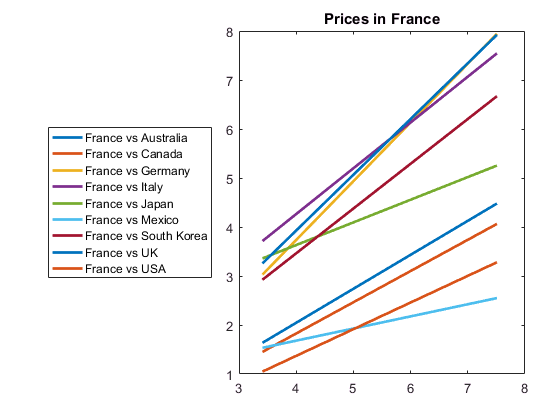


plot(ctryPrice,fits,'LineWidth',2)
title(['Prices in ', ctry{1}])
legend(legabv,'location','westoutside')

size(Slope)

ans =      1     9

size(Slope,2)

ans = 9

length(Slope)

ans = 9

numel(Slope)

ans = 9

idx = menu('Select a country:', country)

idx = 4

ctry = country{idx}

ctry = Germany

ctry = input('Enter a country: ','s');



iskeyword

ans =     'break'
    'case'
    'catch'
    'classdef'
    'continue'
    'else'
    'elseif'
    'end'
    'for'
    'function'
    'global'
    'if'
    'otherwise'
    'parfor'
    'persistent'
    'return'
    'spmd'
    'switch'
    'try'
    'while'


functionq = 3

functionq = 3